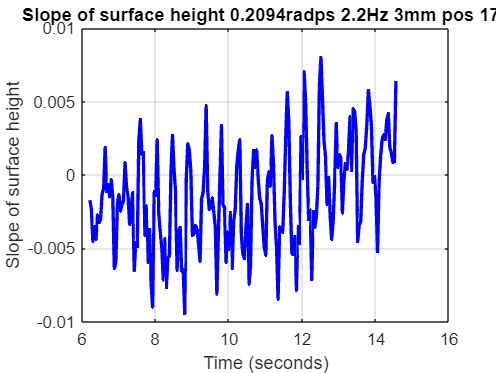

% Code for two options: plot the slope over the short axis as a function of
% the position on the long axis, or plot the slope over the short axis as a
% function of time, set at one location

tic;

clear 
close all
clc

%% Parameters
date = '10';
rot_rate = 0.2094;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 3;

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\Trend\\', date, date, rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Mode selection: 'long_axis' or 'time'
mode = 'time';  % Change this to 'time' for time analysis, or 'long_axis' for long axis analysis

%% Common Parameters
% Specific point or range of points for slope calculation
selected_long_axis_point = 170;  % Used in 'time' mode
start_frame = 150;  % Start of frame number for time mode
end_frame = 350;  % End of frame number for time mode
frame_num = 260;  % Single frame number for long axis mode

%% Frame rate
frame_rate = 23.98;  % Frame rate in frames per second


%% Mode 1: Slope across long axis for a specific frame
if strcmp(mode, 'long_axis')
    % Construct the file name for the specified frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

    % Compute the surface height
    h_0 = 150; % surface-pattern distance in mm
    h = surfheight(dr_new, h_0);
    surface_height = h.w;

    % Initialize array to store slopes
    num_long_axis_points = size(surface_height, 1);
    slopes = zeros(num_long_axis_points, 1);

    % Calculate slopes along the short axis for each long axis point
    for i = 1:num_long_axis_points
        surf_height_short_axis = surface_height(i, :);
        ampl_short_axis = surf_height_short_axis;
        values_short_axis = h.y / 10;  % Convert to cm
        
        % Linear fit for slope calculation
        p = polyfit(values_short_axis, ampl_short_axis, 1);  
        slopes(i) = p(1);  % Store the slope
    end

    % Plot slopes over long axis points
    values_long_axis = h.x / 10;  % Convert to cm
    plot(values_long_axis, slopes, 'b', 'LineWidth', 2);
    title(sprintf('Slope over long axis for frame %d',frame_num));
    xlabel('Position on long axis (cm)');
    ylabel('Slope of surface height');
    grid on;

    % Save the plot
    %saveas(gcf, fullfile(output_dir, 'slope_vs_long_axis.png'));
    saveas(gcf, fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_slope_vs_long_axis_%s.png',date, rot_rate,freq_value,string(ampl_value), string(frame_num))));

    %% Mode 2: Slope over time (frames) at a specific long axis point
elseif strcmp(mode, 'time')
    % Initialize array to store slopes for each frame
    slopes_over_time = zeros(end_frame - start_frame + 1, 1);
    frame_numbers = start_frame:end_frame;

    % Calculate time in seconds for each frame
    time_in_seconds = (frame_numbers - 1) / frame_rate;

    % Iterate over each frame to calculate the slope for the selected long axis point
    for frame_num = start_frame:end_frame
        % Construct the file name for the current frame
        frame_str = sprintf('%04d', frame_num);
        file_name = [base_file_name, frame_str, file_extension];
        input_file = fullfile(input_dir, file_name);

        % Load the data
        dr = loadvec(input_file);

        % Process the data: remove rows and columns with only zeros
        dr_new = dr;
        dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
        dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
        dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
        dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
        dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
        dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

        % Compute the surface height
        h_0 = 150; % surface-pattern distance in mm
        h = surfheight(dr_new, h_0);
        surface_height = h.w;

        % Surface height on short axis for the selected long axis point
        surf_height_short_axis = surface_height(selected_long_axis_point, :);
        ampl_short_axis = surf_height_short_axis;
        values_short_axis = h.y / 10;  % Convert to cm

        % Linear fit for slope calculation
        p = polyfit(values_short_axis, ampl_short_axis, 1);  
        slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
    end

    % Plot slopes over time (in seconds)
    plot(time_in_seconds, slopes_over_time, 'b', 'LineWidth', 2);
    title(sprintf('Slope of surface height %sradps %sHz %smm pos %d',rot_rate,freq_value,string(ampl_value),selected_long_axis_point));
    xlabel('Time (seconds)');
    ylabel('Slope of surface height');
    grid on;

    % Save the plot
    saveas(gcf, fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.png',rot_rate,freq_value,string(ampl_value),selected_long_axis_point)));
end


toc;

Elapsed time is 592.567793 seconds.


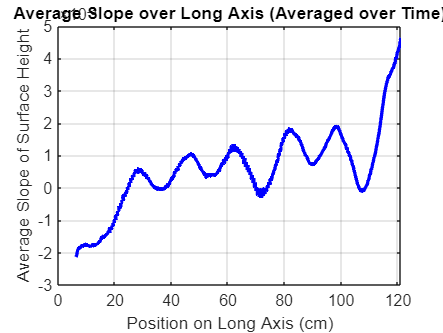

% To plot the average slope (averaged out over time/all the frames) as a
% function of the long axis location

tic;

clear 
close all
clc

%% Parameters
ampl_value = 7;
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\20240909_full_plate_final\\20240909_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\20240909_full_plate_final_results\\20240909_%sradps_%sHz_%smm_full_plate\\Trend\\', rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('20240909_%sradps_%sHz_%smm_full_plate_frame_', rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Common Parameters
start_frame = 190;  % Start of frame number for time mode
end_frame = 350;  % End of frame number for time mode
frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize for Averaging Slopes Over Time
% First, we'll compute the slopes for each frame and each long axis point
% Then, we'll average them over time
first_frame_str = sprintf('%04d', start_frame);
first_file_name = [base_file_name, first_frame_str, file_extension];
first_input_file = fullfile(input_dir, first_file_name);

% Load the first frame data to get the dimensions
dr_first = loadvec(first_input_file);
dr_first.x(:, all(dr_first.vy == 0, 2)) = [];
dr_first.y(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vx(:, all(dr_first.vx == 0, 1)) = [];
dr_first.vx(all(dr_first.vx == 0, 2), :) = [];
dr_first.vy(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vy(all(dr_first.vy == 0, 2), :) = [];

% Compute the surface height for the first frame to get the size
h_0 = 150; % surface-pattern distance in mm
h_first = surfheight(dr_first, h_0);
surface_height_first = h_first.w;

% Number of points along the long axis and short axis
num_long_axis_points = size(surface_height_first, 1);
num_short_axis_points = size(surface_height_first, 2);

% Initialize a matrix to accumulate the slopes for each point along the long axis
slope_accumulator = zeros(num_long_axis_points, end_frame - start_frame + 1);

%% Iterate over frames to calculate slopes for each long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data for the current frame
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr.x(:, all(dr.vy == 0, 2)) = [];
    dr.y(:, all(dr.vy == 0, 1)) = [];
    dr.vx(:, all(dr.vx == 0, 1)) = [];
    dr.vx(all(dr.vx == 0, 2), :) = [];
    dr.vy(:, all(dr.vy == 0, 1)) = [];
    dr.vy(all(dr.vy == 0, 2), :) = [];

    % Compute the surface height for this frame
    h = surfheight(dr, h_0);
    surface_height = h.w;

    % Calculate the slope along the short axis for each long axis point
    for i = 1:num_long_axis_points
        surf_height_short_axis = surface_height(i, :);
        ampl_short_axis = surf_height_short_axis;
        values_short_axis = h.y / 10;  % Convert to cm
        
        % Linear fit for slope calculation
        p = polyfit(values_short_axis, ampl_short_axis, 1);  
        slope_accumulator(i, frame_num - start_frame + 1) = p(1);  % Store the slope for this frame
    end
end

%% Calculate the average slope over time for each long axis point
average_slope = mean(slope_accumulator, 2);

%% Plot the average slope over the long axis
values_long_axis = h.x / 10;  % Convert to cm
plot(values_long_axis, average_slope, 'b', 'LineWidth', 2);
title('Average Slope over Long Axis (Averaged over Time)');
xlabel('Position on Long Axis (cm)');
ylabel('Average Slope of Surface Height');
grid on;

% Save the plot
saveas(gcf, fullfile(output_dir, sprintf('average_%d_to_%d_slope_vs_long_axis.png',start_frame,end_frame)));


toc;

% % Surface height on short axis
% % Plot the amplitude/surface height over the short axis
% surf_height_short_axis = surface_height(170,:);
% ampl_short_axis = surf_height_short_axis;
% values_short_axis = h.y/10; % in cm
% plot(values_short_axis,surf_height_short_axis)
% title('Surface height over short axis')
% xlabel('Position on short axis (cm)')
% ylabel('Surface height (mm)')
% 
% p = polyfit(values_short_axis, ampl_short_axis, 1);  % Degree 1 for a linear trend
% trendline = polyval(p, values_short_axis);           % Compute the trendline
% plot(values_short_axis, ampl_short_axis, 'b');       % Plot original data
% hold on;
% plot(values_short_axis, trendline, 'r', 'LineWidth', 2);  % Plot the trendline
% hold off;
% slope = p(1)



% output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_surf_height_short);
% output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_surf_height_short);

